
% plant for the magnetic ball problem

A = [0 1 0;64.4 0 -16;0 0 -100];
B = [0;0;100];
C = [1 0 0];
D = [0];

% disturbance description

E=B;
F=0;

% this command prints out the poles and zeros in
% the format   8.0250e+000
format short e

plant_eigenvalues =  eig(A)

plant_eigenvalues =    8.0250e+00
  -8.0250e+00
  -1.0000e+02


plant_zeros =   tzero(A,B,C,D)


plant_zeros =

  0×1 empty double column vector



## Part (a)

% various pole locations....

% First the bad design from the problem set -- you want a better design!!!!!!!!!!!
% psf = [-6+6*j   -6-6*j   -20];
% pobs = [-12+12*j  -12-12*j  -40  -5];
% design the controller with state feedback and bias estimator
psf = [-3 -4 -5] *3;
pobs = [-2 -3 -4 -5] * 100;

% dimensions of system (makes it easier to specify closed loop
% system matrices)

n = size(A,1);    % #plant states
p = size(B,2);    % #inputs
q = size(C,1);    % #outputs
m = size(E,2);    % #disturbance states

% check the feasibility conditions
% (A,B) stabilizable:
if rank(ctrb(A,B)) == n
    fprintf('true')
end 

true

% (A,C) detectable
if rank(obsv(A,C)) == n
    fprintf('true') 
end 

true

% (3)
if rank([A,B;C,zeros(q,p)]) == n + q
    fprintf('true')
end 

true

% (4)
if rank([A,E;C,F]) == n+m
    fprintf('true')
end 

true


% if the feasibility conditions are satisfied
% then choose K, L, G, H, so that the control signal is given by
% u = -K*xhat + G*r + H*dhat and L is the estimator gain

K =  place(A,B,psf);
Aaug = [A, E; zeros([1,4])];
Baug = [B;0];
Caug = [C,F];

L =  place(Aaug',Caug',pobs)'

L =    1.3000e+03
   5.8006e+05
  -6.0000e+06
  -7.5000e+06


%
G = pinv((C / (-A + B*K) * B))

G =   -1.0125e+00


%
H =  -G*(C / (-A + B*K) * E + F)

H =   -1.0000e+00


## Part (b-c)

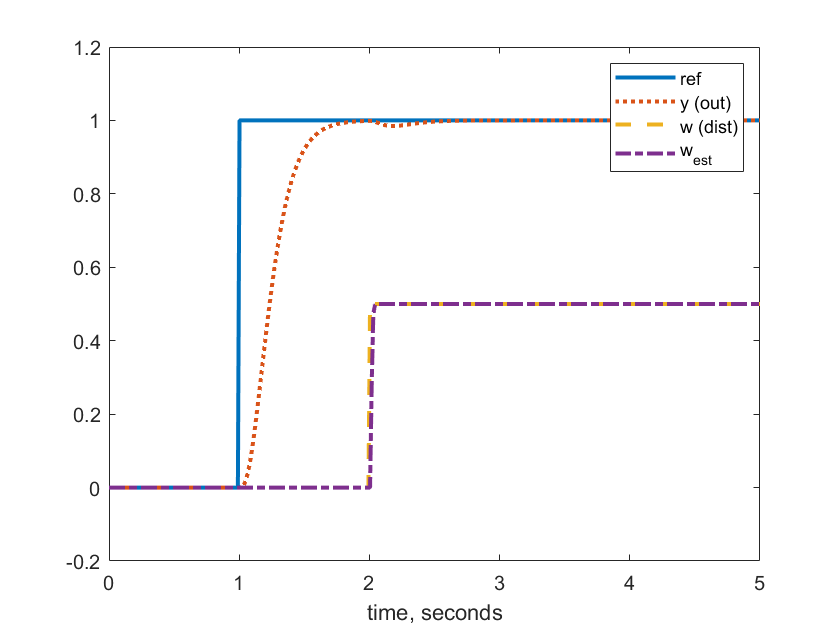

% closed loop state equations (Bcl and Dcl map the reference r and
% disturbance w to the state derivative  and output, respectively)

L1 = L(1:3); L2 = L(end);

% Acl = [A-B*K, B*K, -B*H;
%     zeros([3,3]), A-L1*C, E;
%     zeros([1,3]), -L2*C, 0];
% Bcl = [B*G, E;zeros([3,1]), E; zeros([1,2])];
% Ccl = [C,zeros([1,4])];
% Dcl = zeros([1,2]);
% Cux = [-K, K, -H];
% Dux = [G 0];

Acl = [A, -B*K, B*H;
    L1*C, A-B*K-L1*C, E+B*H-L1*F;
    L2*C, -L2*C, -L2*F];

Bcl = [B*G E;B*G,zeros(3,1);zeros([1,2])];

Ccl = [C,zeros([1,4])];

Dcl = zeros([1,2]);

Cux = [zeros([1,3]) -K H];

Dux = [G 0];

% create step command r and disturbance w

clear r w
t = linspace(0,5,400);

for i = 1:length(t)
    
    % unit step command at t = 1
    
    if t(i) <= 1
        r(i) = 0;
    elseif t(i) >= 1
        r(i) = 1;
    end
    
    % 0.5 step disturbance at t = 2
    if t(i) <= 2
        w(i) = 0;
    elseif t(i) >= 2
        w(i) = .5;
    end
end


% simulate response of y and u to command and disturbance
[y,x] = lsim(Acl,Bcl,Ccl,Dcl,[r'  w'],t);
[u,x] = lsim(Acl, Bcl, Cux, Dux,[r' w'],t); 

figure(1)
clf

plot(t,r,'-',t,y,':',t,w,'--',t,x(:,2*n+1:2*n+m),'-.')
%plot(t,r,'w-',t,w,'w--',t,x(:,2*n+1:2*n+m),'w-.')

xlabel('time, seconds')
legend('ref','y (out)','w (dist)','w_{est}')
set(findall(gcf,'type','line'),'linewidth',2)

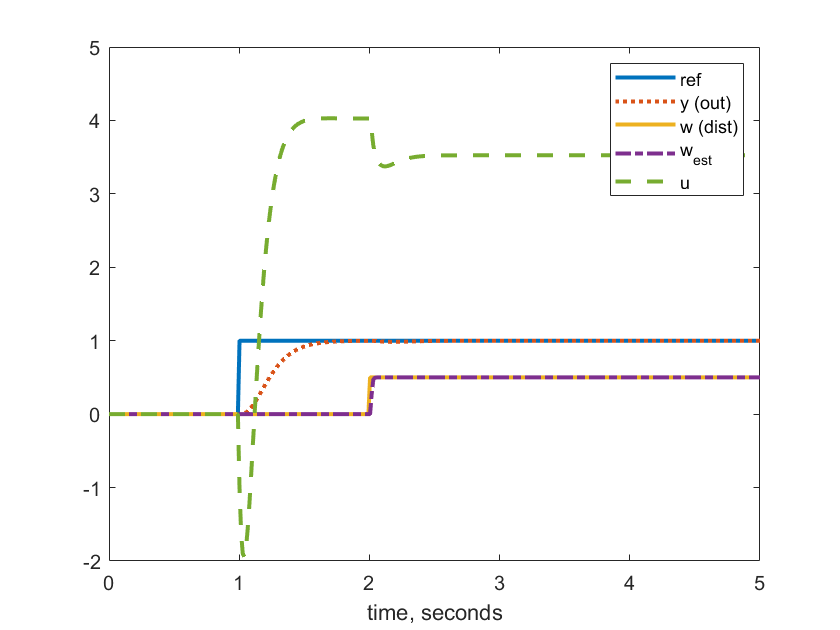


figure(2)
clf

plot(t,r,'-',t,y,':',t,w,'-',t,x(:,2*n+1:2*n+m),'-.',t,u,'--')
xlabel('time, seconds')
legend('ref','y (out)','w (dist)','w_{est}','u')
set(findall(gcf,'type','line'),'linewidth',2)

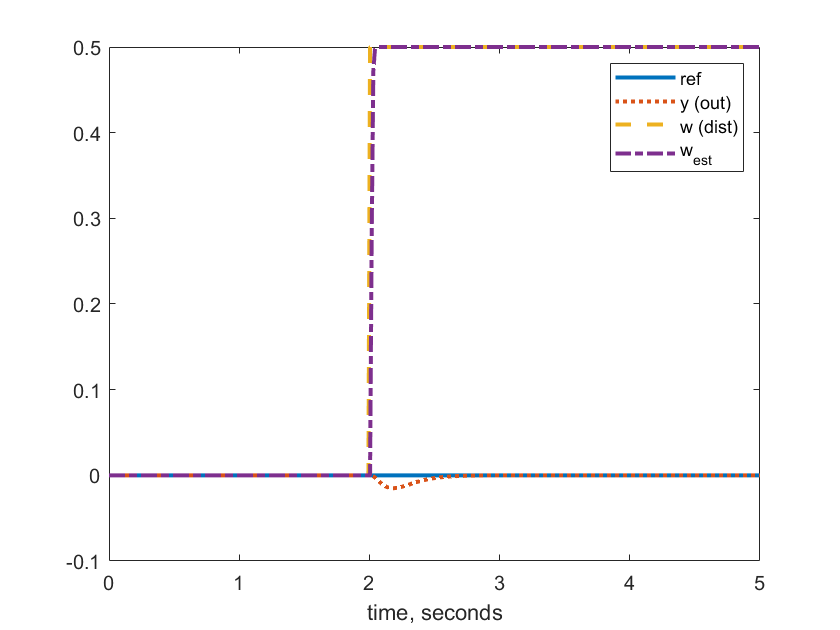


% simulate the design with  disturbance ONLY
% this makes it easier to separate the disturbance response
% from the command response

clear r w
t = linspace(0,5,400);
for i = 1:length(t)
    if t(i) <= 1
        r(i) = 0;           % zero step command
    elseif t(i) >= 1
        r(i) = 0;
    end
    if t(i) <= 2         % 0.5 step disturbance at t = 2
        w(i) = 0;
    elseif t(i) >= 2
        w(i) = .5;
    end
end



[y,x] = lsim(Acl,Bcl,Ccl,Dcl,[r'  w'],t);
[u,x] = lsim(Acl,Bcl,Cux,Dux,[r'  w'],t);



figure(3)
clf


plot(t,r,'-',t,y,':',t,w,'--',t,x(:,2*n+1:2*n+m),'-.')
%plot(t,r,'w-',t,w,'w--',t,x(:,2*n+1:2*n+m),'w-.')

xlabel('time, seconds')
legend('ref','y (out)','w (dist)','w_{est}')
set(findall(gcf,'type','line'),'linewidth',2)

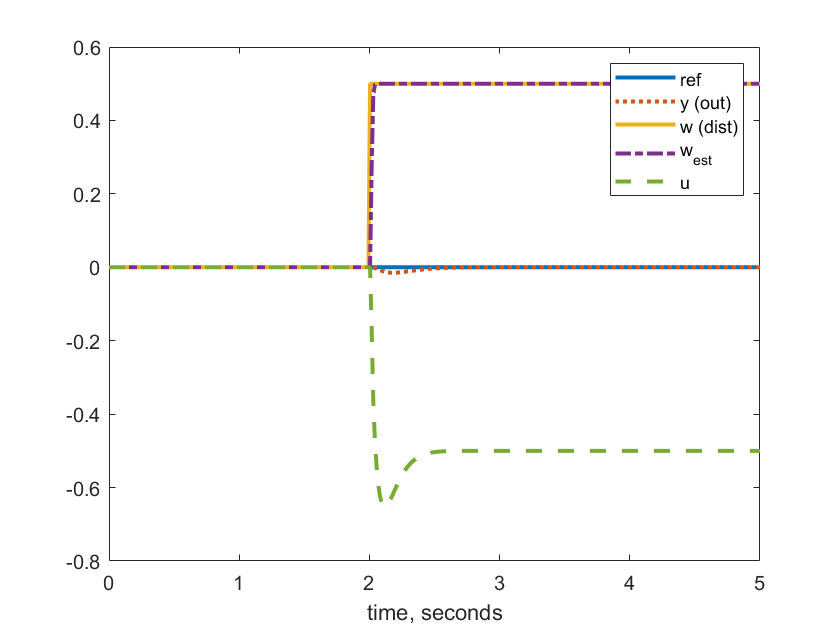




figure(4)
clf


plot(t,r,'-',t,y,':',t,w,'-',t,x(:,2*n+1:2*n+m),'-.',t,u,'--')
%plot(t,r,'w-',t,w,'w--',t,x(:,2*n+1:2*n+m),'w-.')
%axis([0 5  -1 1])
xlabel('time, seconds')
legend('ref','y (out)','w (dist)','w_{est}','u')
set(findall(gcf,'type','line'),'linewidth',2)

## bode plot

% compute closed loop disturbance response
s = tf('s')

s =
 
  s
 
Continuous-time transfer function.



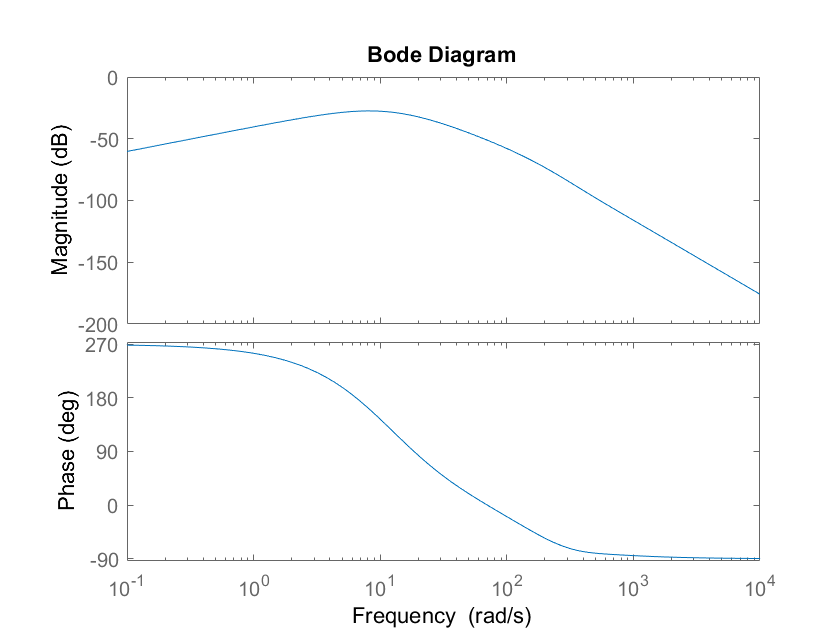

TF = Ccl/(s*eye(7) - Acl)*Bcl(:,2) +0;
% omega = logspace(-3,3)
% [mag,phase] = bode(TF); 

% figure(5)
% clf
% 
% loglog(omega,mag)
% ylabel('magnitude')
% xlabel('frequency, rad/sec')
% title('closed loop disturbance response')
% set(findall(gcf,'type','line'),'linewidth',2)

bode(TF)

How does the control signal change as the command and disturbance response change?

Answer: In this designed system, the disturbance will have little change to the control signal

 Do slower eigenvalues tend to result in a larger or a smaller control signal (or is there no particular

trend)?

Answer: yes.

## P2 Reduced Order Model

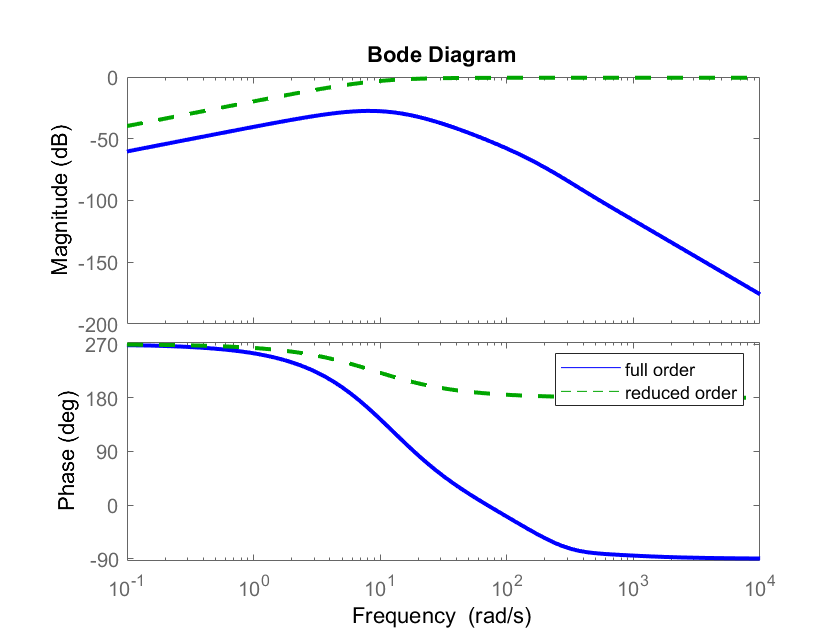

G = ss(Acl,Bcl,Ccl,Dcl);

[am,bm,cm,dm] = canon(Acl,Bcl,Ccl,Dcl,'modal');  % diagonalizes system


[ar,br,cr,dr] = modred(am,bm,cm,dm,[1:6]);

Gr = ss(ar,br,cr,dr);

% compare Bode plots of tf of x
figure(6)
clf

h=bodeplot(G(2),'b-',Gr(2),'g--');
p = getoptions(h); 
p.PhaseWrapping = ['off' ]; 
setoptions(h,p); % Update the Bode plot.
legend('full order','reduced order')
set(findall(gcf,'type','line'),'linewidth',2)

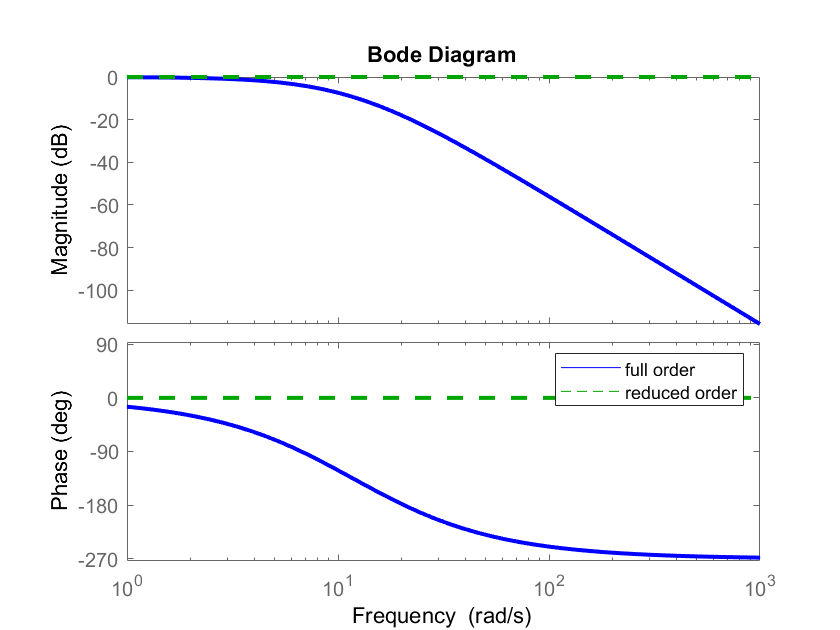

[ar,br,cr,dr] = modred(am,bm,cm,dm,[4:7]);

Gr = ss(ar,br,cr,dr);
% compare Bode plots of tf of w
figure(7)
clf

h=bodeplot(G(1),'b-',Gr(1),'g--');
p = getoptions(h); 
p.PhaseWrapping = 'off'; 
setoptions(h,p); % Update the Bode plot.
legend('full order','reduced order')
set(findall(gcf,'type','line'),'linewidth',2)